clear all; clc;
%==========================================================================
p_3 = [13.75 ; 4.1; 4.3; 3.6; 3.23; 4.2; 2.6; 3.5; 5; 3];
%------------------
a_1 = p_3(1)

a_1 = 13.7500

b_1 = p_3(3)

b_1 = 4.3000

c_1 = p_3(7)

c_1 = 2.6000

mu_1 = p_3(9)

mu_1 = 5

%------------
a_2 = p_3(2)

a_2 = 4.1000

b_2 = p_3(4)

b_2 = 3.6000

c_2 = p_3(8)

c_2 = 3.5000

mu_2 = p_3(10)

mu_2 = 3

%--------------
xi = p_3(5)

xi = 3.2300

lambda = p_3(6)

lambda = 4.2000

%------------------
rho_1 = a_1/(c_1*mu_1)

rho_1 = 1.0577

rho_2 = a_2/(c_2*mu_2)

rho_2 = 0.3905

rho = max(rho_1, rho_2)

rho = 1.0577

%------------------
guess_1 = [1; 1; 1];
x_sol = ecm_equilibrium (p_3,  guess_1)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x_sol =     0.8245
    0.1754
    0.0000


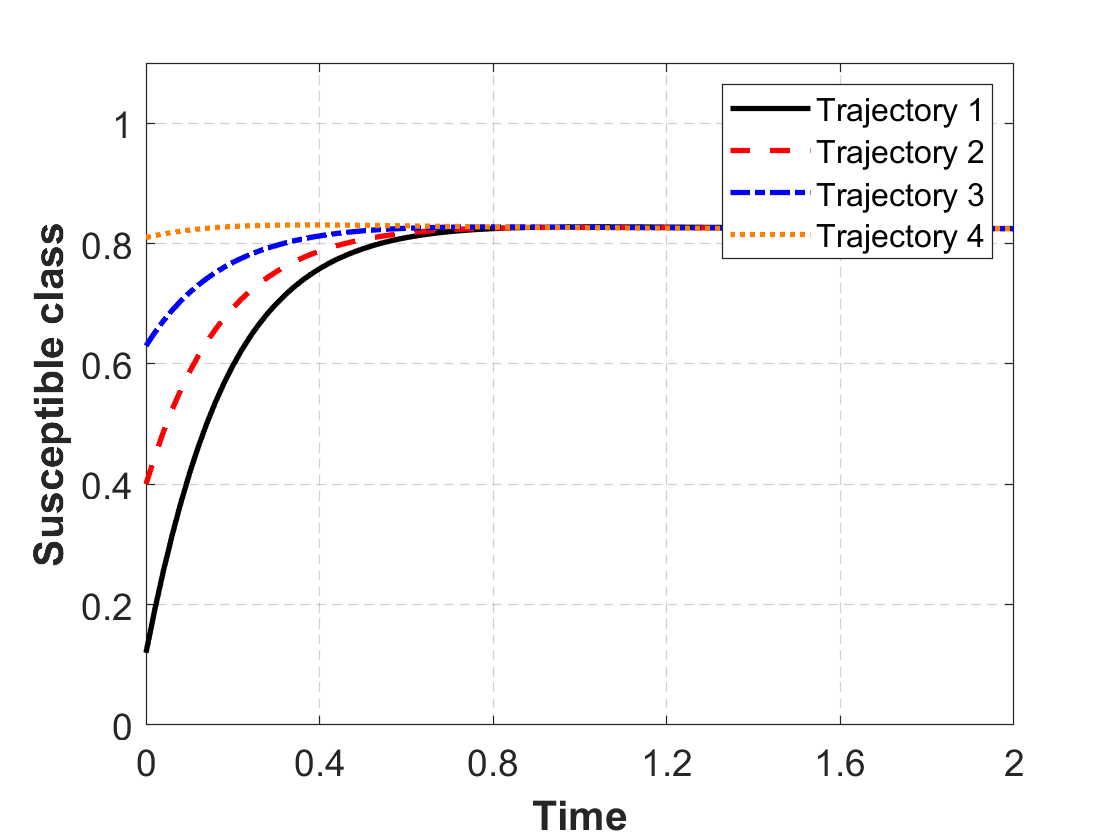

%--------------------------------
n_1 = 100;
T_1 = 2;
%--------------------------------
initial_1 = [0.12; 0.34; 1 - 0.12 - 0.34];
initial_2 = [0.40; 0.25; 1 - 0.40 - 0.25];
initial_3 = [0.63; 0.15; 1 - 0.63 - 0.15];
initial_4 = [0.81; 0.10; 1 - 0.81 - 0.10];
%--------------------------------
[time_1, values_1] = ecm_integration  (p_3, initial_1, n_1, T_1);
[~, values_2] = ecm_integration  (p_3, initial_2, n_1, T_1);
[~, values_3] = ecm_integration  (p_3, initial_3, n_1, T_1);
[~, values_4] = ecm_integration  (p_3, initial_4, n_1, T_1);
%--------------------------------------------------------------------------
%--------------------------------------------------------------------------
figure(1)
plot(time_1, values_1(1,:), 'LineSTyle', '-', 'color', 'k', 'LineWidth', 2);  % blue solid line
hold on
plot(time_1, values_2(1,:), 'LineSTyle', '--', 'color', 'r', 'LineWidth', 2); % red dashed line
hold on
plot(time_1, values_3(1,:), '-.', 'color', 'b', 'LineWidth', 2); % red dashed line
hold on
plot(time_1, values_4(1,:), ':' , 'Color', [1 0.5 0], 'LineWidth', 2); % red dashed line
hold off
% Labels and title
xlabel('Time', 'FontSize', 16, 'FontWeight', 'bold')
ylabel('Susceptible class', 'FontSize', 16, 'FontWeight', 'bold')
%title('Susceptible individuals', 'FontSize', 14, 'FontWeight', 'bold')
% Legend
legend({'Trajectory 1', 'Trajectory 2', 'Trajectory 3', 'Trajectory 4'}, 'FontSize', 12, 'Location', 'northeast')
% Grid
grid on
ax = gca;                     % current axes
ax.GridLineStyle = '--';       % dashed grid lines
ax.GridColor = [0.1 0.1 0.1];  % dark gray color
ax.GridAlpha = 0.2;            % transparency
% Optional: set figure background color
set(gcf, 'Color', [1 1 1])     % white background
ylim([0 1.1])
yticks(0:0.2:1.2)
xticks(0:0.4:2)
ax.XAxis.FontSize = 14;  % x-axis tick labels
ax.YAxis.FontSize = 14; 

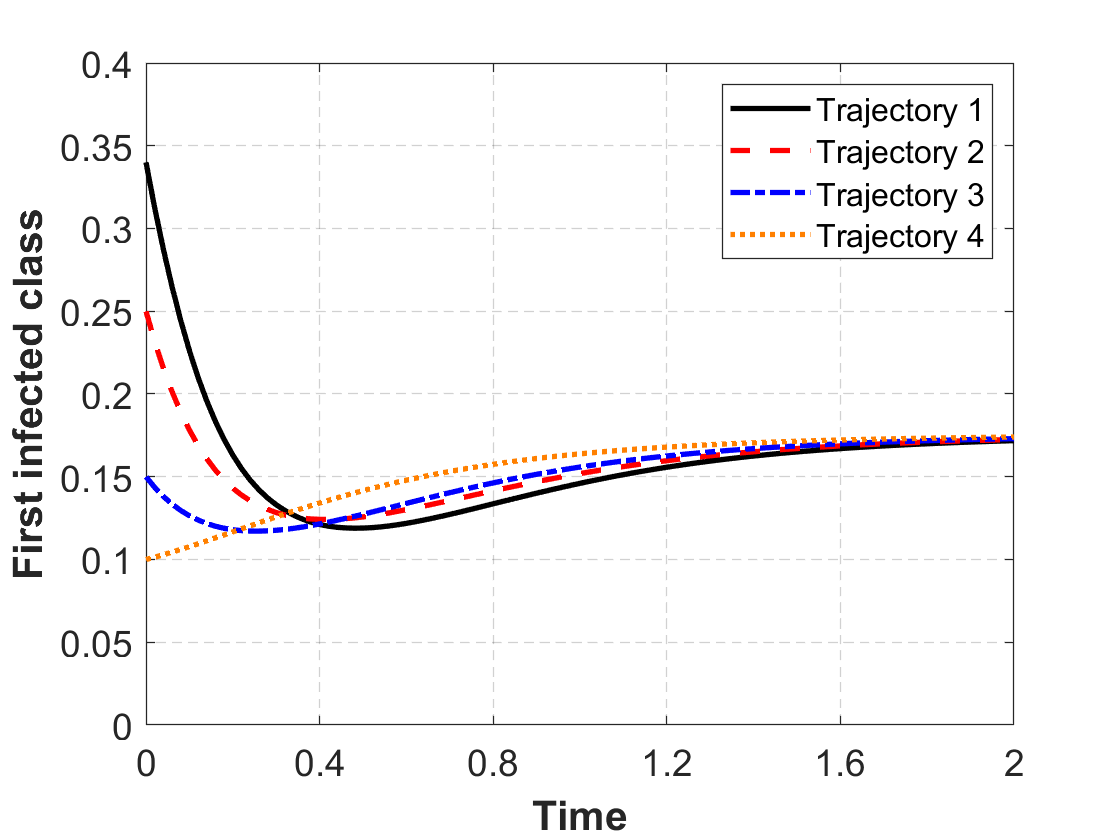

%--------------------------------------------------------------------------
%--------------------------------------------------------------------------
figure(2)
plot(time_1, values_1(2,:), 'LineSTyle', '-', 'color', 'k', 'LineWidth', 2);  % blue solid line
hold on
plot(time_1, values_2(2,:), 'LineSTyle', '--', 'color', 'r', 'LineWidth', 2); % red dashed line
hold on
plot(time_1, values_3(2,:), '-.', 'color', 'b', 'LineWidth', 2); % red dashed line
hold on
plot(time_1, values_4(2,:), ':' , 'Color', [1 0.5 0], 'LineWidth', 2); % red dashed line
hold off
% Labels and title
xlabel('Time', 'FontSize', 16, 'FontWeight', 'bold')
ylabel('First infected class', 'FontSize', 16, 'FontWeight', 'bold')
%title('Susceptible individuals', 'FontSize', 14, 'FontWeight', 'bold')
% Legend
legend({'Trajectory 1', 'Trajectory 2', 'Trajectory 3', 'Trajectory 4'}, 'FontSize', 12, 'Location', 'northeast')
% Grid
grid on
ax = gca;                     % current axes
ax.GridLineStyle = '--';       % dashed grid lines
ax.GridColor = [0.1 0.1 0.1];  % dark gray color
ax.GridAlpha = 0.2;            % transparency
% Optional: set figure background color
set(gcf, 'Color', [1 1 1])     % white background
ylim([0 0.4])
yticks(0:0.05:1.1)
xticks(0:0.4:2)
ax.XAxis.FontSize = 14;  % x-axis tick labels
ax.YAxis.FontSize = 14; 

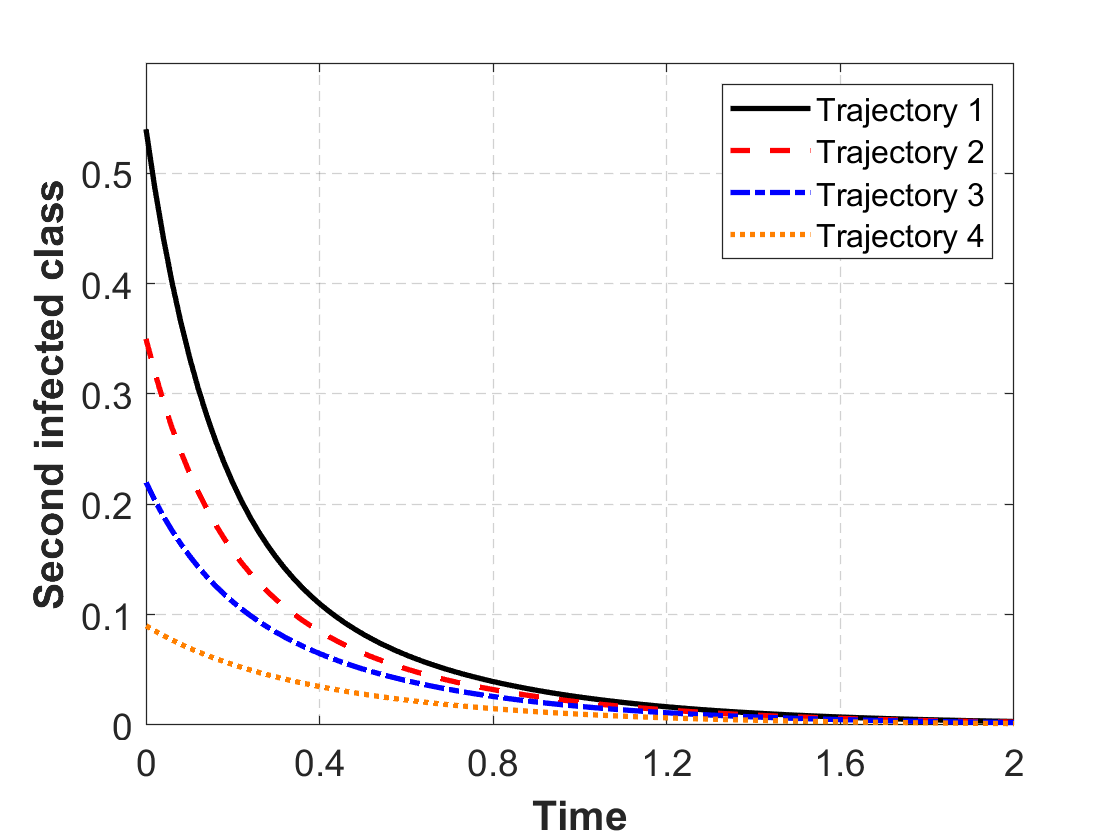

%--------------------------------------------------------------------------
%--------------------------------------------------------------------------
figure(3)
plot(time_1, values_1(3,:), 'LineSTyle', '-', 'color', 'k', 'LineWidth', 2);  % blue solid line
hold on
plot(time_1, values_2(3,:), 'LineSTyle', '--', 'color', 'r', 'LineWidth', 2); % red dashed line
hold on
plot(time_1, values_3(3,:), '-.', 'color', 'b', 'LineWidth', 2); % red dashed line
hold on
plot(time_1, values_4(3,:), ':' , 'Color', [1 0.5 0], 'LineWidth', 2); % red dashed line
hold off
% Labels and title
xlabel('Time', 'FontSize', 16, 'FontWeight', 'bold')
ylabel('Second infected class', 'FontSize', 16, 'FontWeight', 'bold')
%title('Susceptible individuals', 'FontSize', 14, 'FontWeight', 'bold')
% Legend
legend({'Trajectory 1', 'Trajectory 2', 'Trajectory 3', 'Trajectory 4'}, 'FontSize', 12, 'Location', 'northeast')
% Grid
grid on
ax = gca;                     % current axes
ax.GridLineStyle = '--';       % dashed grid lines
ax.GridColor = [0.1 0.1 0.1];  % dark gray color
ax.GridAlpha = 0.2;            % transparency
% Optional: set figure background color
set(gcf, 'Color', [1 1 1])     % white background
ylim([0 0.6])
yticks(0:0.1:1.1)
xticks(0:0.4:2)
ax.XAxis.FontSize = 14;  % x-axis tick labels
ax.YAxis.FontSize = 14; 